# Channel Matched Filter Equalizer

% Uplink
% Max Rate V.S. Number of Antennas
% Linear and Rectangular Formation


## Global Parameter

clc
clearvars

K = 10;
dn = 0.5;

taps = 4;
freq = 20;

use = 5;

time = 100;
cyclic = 20;

shield = taps + freq + 1;
IK = eye(K);

M1_all = [4, 8, 8, 16, 16];
M2_all = [8, 8, 16, 16, 32];
M_all = M1_all .* M2_all;
sample = 5;

alpha = 0.9;
eta = 500;
mu = 0;


## Channel Power Delay Profile

u = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * u(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * u(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end


## Search Tree

for index = 1 : sample
    
    M = M_all(index);
    M1 = M1_all(index);
    M2 = M2_all(index);
    
    for i = 1 : M
        for j = 1 : M
            dist(i, j) = abs(i - j) * dn;
        end
    end
    arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
    arg = sqrt(arg);
    bsl_1D = abs(besseli(0, arg) ./ besseli(0, eta));
    exp_1D = alpha .^ dist;
    clear dist;
    
    i = 1;
    for c1 = 1 : M1
        for r1 = 1 : M2
            j = 1;
            for c2 = 1 : M1
                for r2 = 1 : M2
                    dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                    j = j + 1;
                end
            end
            i = i + 1;
        end
    end
    dist = sqrt(dist .* dn);
    arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
    arg = sqrt(arg);
    bsl_2D = abs(besseli(0, arg) ./ besseli(0, eta));
    exp_2D = alpha .^ dist;
    clear dist;
    
    %{
    for n = 1 : use
        S(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
        Z(:, :, n) = (sqrt(0.5)) * (randn(M, time + cyclic) + 1i * randn(M, time + cyclic));
        
        for l = 1 : taps
            D1 = D(:, :, l) .^ (0.5);
            H1 = (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
            Hl_exp_1D(:, :, l, n) = (exp_1D ^ (0.5)) * H1 * D1;
            Hl_bsl_1D(:, :, l, n) = (bsl_1D ^ (0.5)) * H1 * D1;
            Hl_exp_2D(:, :, l, n) = (exp_2D ^ (0.5)) * H1 * D1;
            Hl_bsl_2D(:, :, l, n) = (bsl_2D ^ (0.5)) * H1 * D1;
        end
        
        Ql_exp_1D(:, :, l, n) = Hl_exp_1D(:, :, l, n)';
        Ql_bsl_1D(:, :, l, n) = Hl_bsl_1D(:, :, l, n)';
        Ql_exp_2D(:, :, l, n) = Hl_exp_2D(:, :, l, n)';
        Ql_bsl_2D(:, :, l, n) = Hl_bsl_2D(:, :, l, n)';
        
        [AQ1(n)] = Signal_Power(taps, Ql_exp_1D(:, :, :, n));
        [AQ2(n)] = Signal_Power(taps, Ql_bsl_1D(:, :, :, n));
        [AQ3(n)] = Signal_Power(taps, Ql_exp_2D(:, :, :, n));
        [AQ4(n)] = Signal_Power(taps, Ql_bsl_2D(:, :, :, n));
        
        for l = 1 : taps
            E1(:, :, l, n) = (Ql_exp_1D(:, :, l, n)) * (Hl_exp_1D(:, :, l, n));
            E2(:, :, l, n) = (Ql_bsl_1D(:, :, l, n)) * (Hl_bsl_1D(:, :, l, n));
            E3(:, :, l, n) = (Ql_exp_2D(:, :, l, n)) * (Hl_exp_2D(:, :, l, n));
            E4(:, :, l, n) = (Ql_bsl_2D(:, :, l, n)) * (Hl_bsl_2D(:, :, l, n));
        end
    end
    
    an1 = 1 / mean(AQ1);
    an2 = 1 / mean(AQ2);
    an3 = 1 / mean(AQ3);
    an4 = 1 / mean(AQ4);
    
    clear AQ1 AQ2 AQ3 AQ4;
    
    for n = 1 : use
        for k = 1 : K
            for l = 1 : taps
                gk1(k, :, n, l) = E1(k, k, l, n) * S(k, :, n);
                gk2(k, :, n, l) = E2(k, k, l, n) * S(k, :, n);
                gk3(k, :, n, l) = E3(k, k, l, n) * S(k, :, n);
                gk4(k, :, n, l) = E4(k, k, l, n) * S(k, :, n);
            end
        end
    end
    
    gi1 = sum(gk1, 4);
    gi2 = sum(gk2, 4);
    gi3 = sum(gk3, 4);
    gi4 = sum(gk4, 4);
    
    clear gk1 gk2 gk3 gk4;
    
    X = S;
    for j = 1 : cyclic
        X(:, time + j, :) = X(:, j, :);
    end
    
    for n = 1 : use
        for l = 1 : taps
            for j = 0 : time + cyclic -1
                rk1(:, j + 1, n, l) = (Hl_exp_1D(:, :, l, n)) * X(:, mod(j - l, time) + 1, n);
                rk2(:, j + 1, n, l) = (Hl_bsl_1D(:, :, l, n)) * X(:, mod(j - l, time) + 1, n);
                rk3(:, j + 1, n, l) = (Hl_exp_2D(:, :, l, n)) * X(:, mod(j - l, time) + 1, n);
                rk4(:, j + 1, n, l) = (Hl_bsl_2D(:, :, l, n)) * X(:, mod(j - l, time) + 1, n);
            end
        end
    end
    r1 = sum(rk1, 4);
    clear rk1;
    r2 = sum(rk2, 4);
    clear rk2;
    r3 = sum(rk3, 4);
    clear rk3;
    r4 = sum(rk4, 4);
    clear rk4;
    
    for n = 1 : use
        for l = 1 : taps
            for j = 0 : time + cyclic - 1
                yk1(:, j + 1, n, l) = Ql_exp_1D(:, :, l, n) * r1(:, mod(j + l, time) + 1, n);
                yk2(:, j + 1, n, l) = Ql_bsl_1D(:, :, l, n) * r2(:, mod(j + l, time) + 1, n);
                yk3(:, j + 1, n, l) = Ql_exp_2D(:, :, l, n) * r3(:, mod(j + l, time) + 1, n);
                yk4(:, j + 1, n, l) = Ql_bsl_2D(:, :, l, n) * r4(:, mod(j + l, time) + 1, n);
            end
        end
    end
    y1 = sum(yk1, 4);
    clear yk1 r1;
    y2 = sum(yk2, 4);
    clear yk2 r2;
    y3 = sum(yk3, 4);
    clear yk3 r3;
    y4 = sum(yk4, 4);
    clear yk4 r4;
    
    ni1 = y1(:, 1 : time, :) - gi1;
    ni2 = y2(:, 1 : time, :) - gi2;
    ni3 = y3(:, 1 : time, :) - gi3;
    ni4 = y4(:, 1 : time, :) - gi4;
    
    E1_sum = sum(mean(E1, 4), 3);
    E2_sum = sum(mean(E2, 4), 3);
    E3_sum = sum(mean(E3, 4), 3);
    E4_sum = sum(mean(E4, 4), 3);
    
    clear E1 E2 E3 E4;
    
    for n = 1 : use
        for k = 1 : K
            Sk1 = abs(an1 * (E1_sum(k, k))) ^ 2;
            Sk2 = abs(an2 * (E2_sum(k, k))) ^ 2;
            Sk3 = abs(an3 * (E3_sum(k, k))) ^ 2;
            Sk4 = abs(an4 * (E4_sum(k, k))) ^ 2;
    
            Sn1 = var(ni1(k, :, n), 0, 2);
            Sn2 = var(ni2(k, :, n), 0, 2);
            Sn3 = var(ni3(k, :, n), 0, 2);
            Sn4 = var(ni4(k, :, n), 0, 2);
            
            SNR1 = Sk1 / Sn1;
            SNR2 = Sk2 / Sn2;
            SNR3 = Sk3 / Sn3;
            SNR4 = Sk4 / Sn4;
            
            Rk1(k, n) = log2(1 + SNR1);
            Rk2(k, n) = log2(1 + SNR2);
            Rk3(k, n) = log2(1 + SNR3);
            Rk4(k, n) = log2(1 + SNR4);
        end
    end
    R1(index) = 0.5 * mean(sum(Rk1, 1));
    R2(index) = 0.5 * mean(sum(Rk2, 1));
    R3(index) = 0.5 * mean(sum(Rk3, 1));
    R4(index) = 0.5 * mean(sum(Rk4, 1));
    
    clear Hl_exp_1D Hl_bsl_1D Hl_exp_2D Hl_bsl_2D;
    clear Ql_exp_1D Ql_bsl_1D Ql_exp_2D Ql_bsl_2D;
    
    clear E1_sum E2_sum E3_sum E4_sum;
    clear ni1 ni2 ni3 ni4;
    clear AWGN1 AWGN2 AWGN3 AWGN4;
    clear Rk1 Rk2 Rk3 Rk4;
    clear S Z;
    %}
    
    for l = 1 : taps
        for k = 1 : K
            V1(l, k) = d(l, k) ^ 2;
            V2(l, k) = d(l, k);
        end
    end
    first = sum(V1, 1);
    second = sum(V2, 1);
    
    for k = 1 : K
        Vg1 = (1 / (M * K)) * (trace(exp_1D * exp_1D') * (first(k)) + (trace(exp_1D) ^ 2) * (second(k)) .^ 2);
        Vn1 = 1 * (trace(exp_1D * exp_1D') / M) * (1 - V2(k) / K);
        R1_k(k) = log2(1 + Vg1 / Vn1);
        
        Vg2 = (1 / (M * K)) * (trace(bsl_1D * bsl_1D') * (first(k)) + (trace(bsl_1D) ^ 2) * (second(k)) .^ 2);
        Vn2 = 1 * (trace(bsl_1D * bsl_1D') / M) * (1 - V2(k) / K);
        R2_k(k) = log2(1 + Vg2 / Vn2);
        
        Vg3 = (1 / (M * K)) * (trace(exp_2D * exp_2D') * (first(k)) + (trace(exp_2D) ^ 2) * (second(k)) .^ 2);
        Vn3 = 1 * (trace(exp_2D * exp_2D') / M) * (1 - V2(k) / K);
        R3_k(k) = log2(1 + Vg3 / Vn3);
        
        Vg4 = (1 / (M * K)) * (trace(bsl_2D * bsl_2D') * (first(k)) + (trace(bsl_2D) ^ 2) * (second(k)) .^ 2);
        Vn4 = 1 * (trace(bsl_2D * bsl_2D') / M) * (1 - V2(k) / K);
        R4_k(k) = log2(1 + Vg4 / Vn4);
        
    end
    R1(index) = 0.5 * sum(R1_k);
    R2(index) = 0.5 * sum(R2_k);
    R3(index) = 0.5 * sum(R3_k);
    R4(index) = 0.5 * sum(R4_k);

end

factor = (time) / (time + cyclic);

R1 = factor * R1;
R2 = factor * R2;
R3 = factor * R3;
R4 = factor * R4;


## Visualization

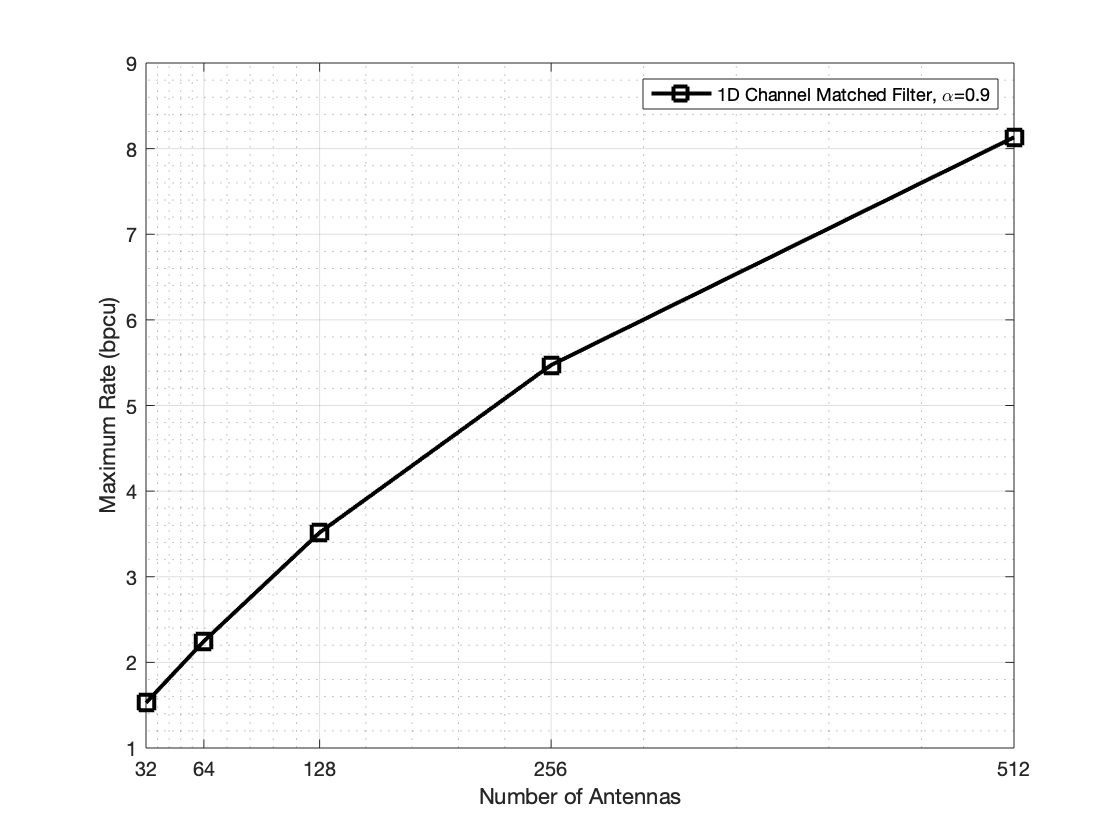

angel = strcat('\pi/', num2str(pi / mu));

if (mu == 0)
    angel = num2str(0);
end

name_a = '1D Channel Matched Filter';
name_b = '2D Channel Matched Filter';

name1 = strcat(name_a, ', \alpha=', num2str(alpha));
% name2 = strcat(name_a, ', \eta=', num2str(eta), ', \mu=', angel);
name2 = strcat(name_a, ', \eta=', num2str(eta));
name3 = strcat(name_b, ', \alpha=', num2str(alpha));
% name4 = strcat(name_b, ', \eta=', num2str(eta), ', \mu=', angel);
name4 = strcat(name_b, ', \eta=', num2str(eta));

x_label = 'Number of Antennas';
y_label = 'Maximum Rate (bpcu)';

style = '-ks';


figure;
plot(M_all, R1, style, 'DisplayName', name1, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M_all);
xlim([M_all(1), M_all(sample)]);
legend();
grid on;
grid minor;

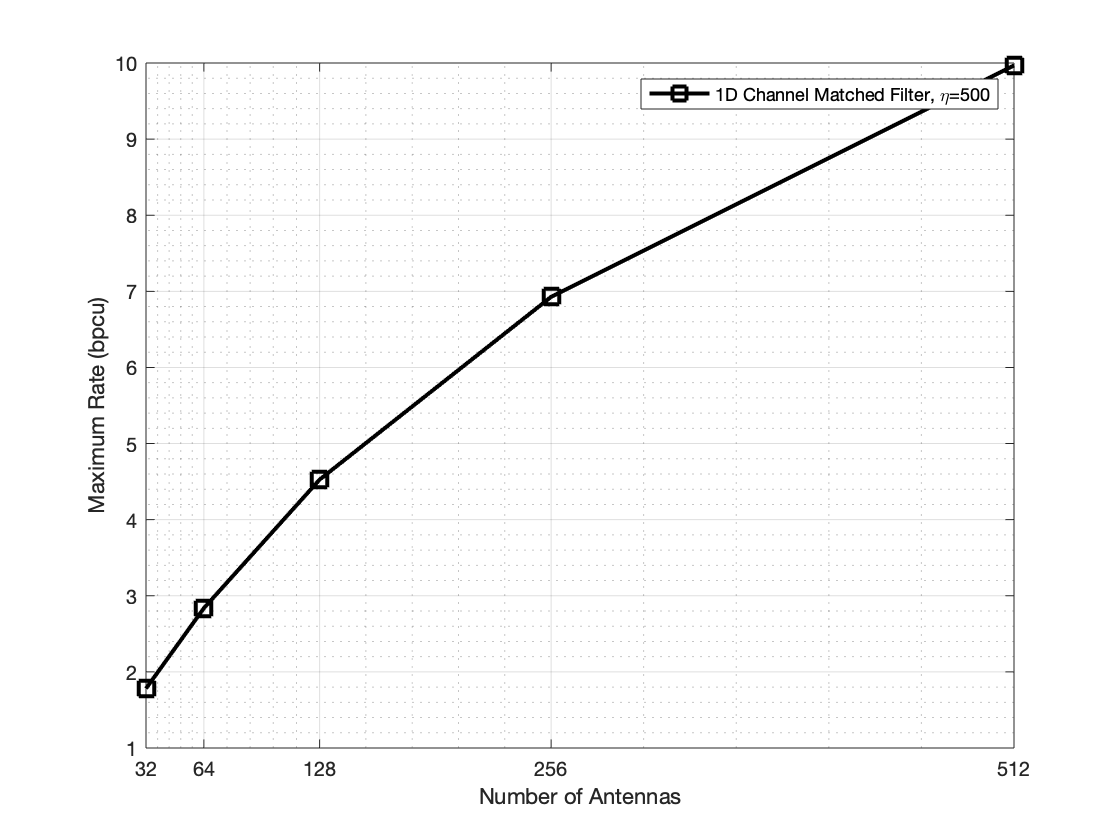



figure;
plot(M_all, R2, style, 'DisplayName', name2, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M_all);
xlim([M_all(1), M_all(sample)]);
legend();
grid on;
grid minor;

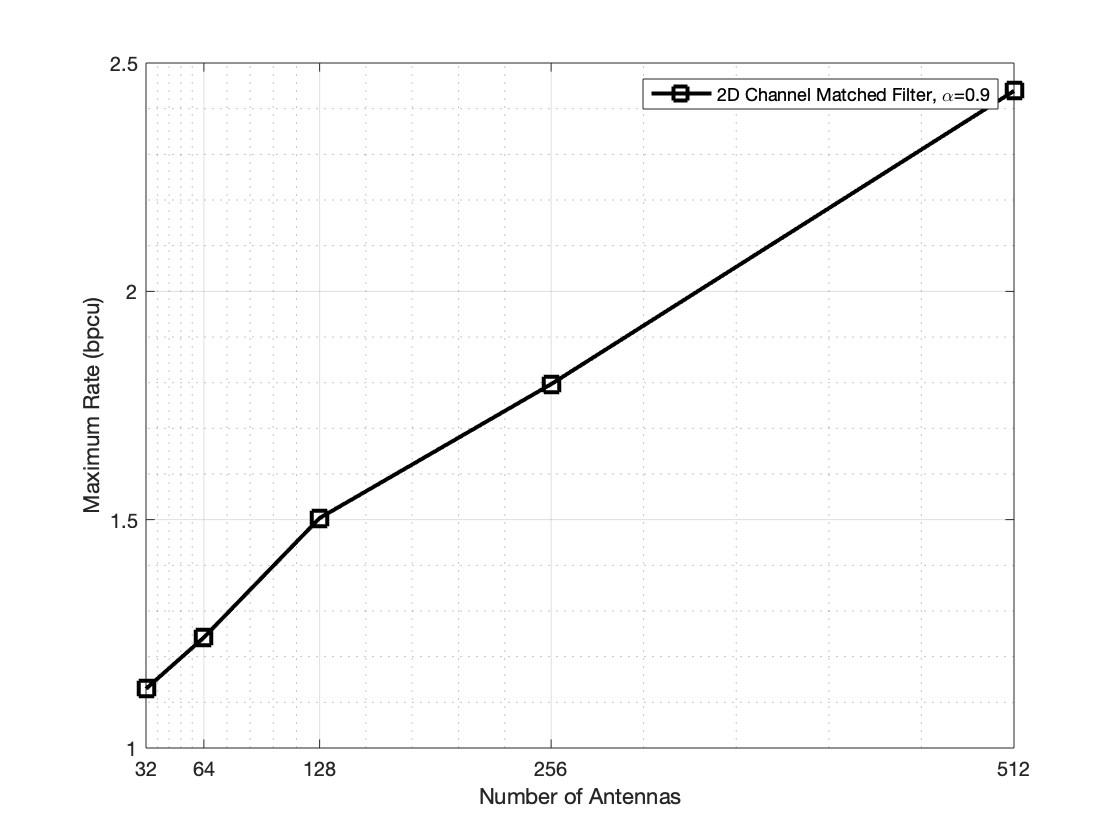



figure;
plot(M_all, R3, style, 'DisplayName', name3, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M_all);
xlim([M_all(1), M_all(sample)]);
legend();
grid on;
grid minor;

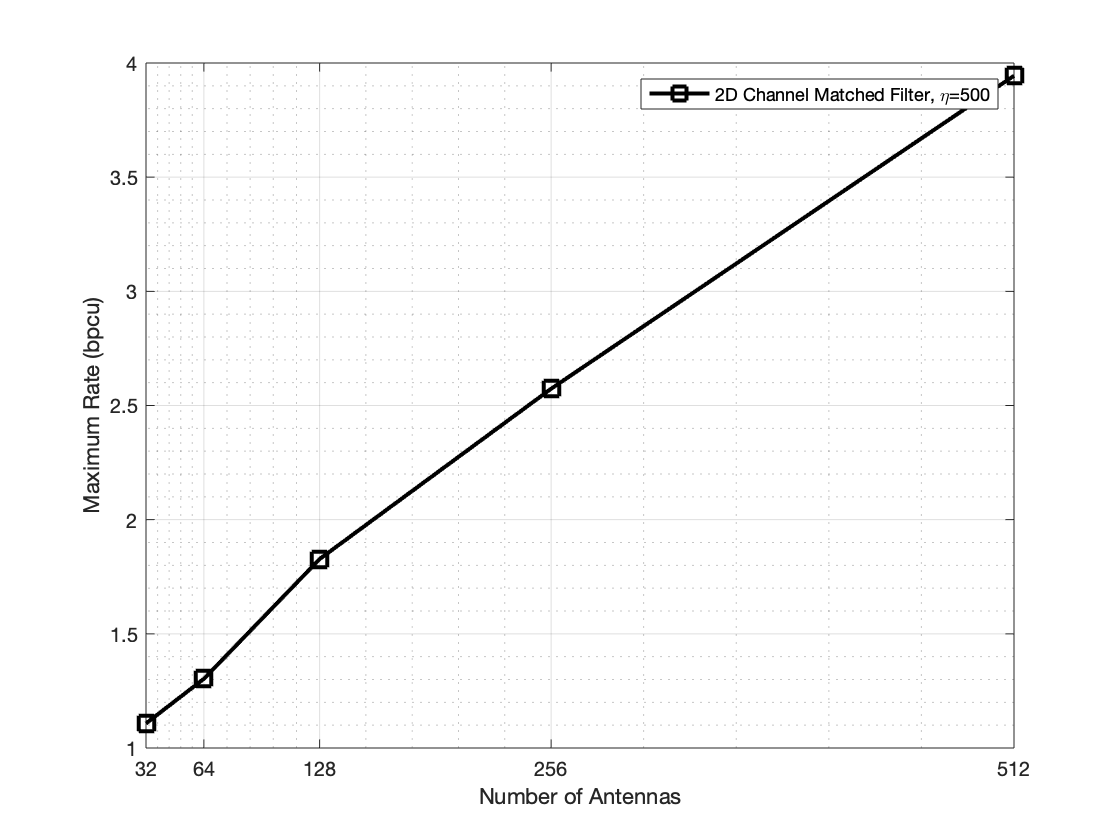



figure;
plot(M_all, R4, style, 'DisplayName', name4, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M_all);
xlim([M_all(1), M_all(sample)]);
legend();
grid on;
grid minor;